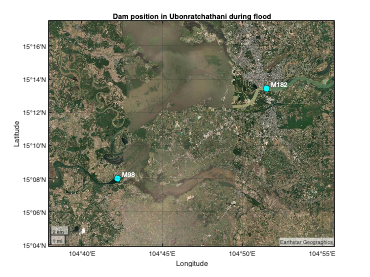

% clear workspaces
clc, clearvars, close all

lat1 = 15.2235;
lon1 = 104.8580;
text1 = "M182";

lat2 = 15.1334;
lon2 = 104.7033;
towerHeight2 = 30.5;
text2 = "M98";
figure
basemap = "satellite";
geobasemap(basemap)

geoplot([lat1 lat2],[lon1 lon2], ...
    LineStyle="none",Marker="o",MarkerSize=10, ...
    MarkerEdgeColor="k",MarkerFaceColor="c")
gx = gca;
zoomLevel = floor(gx.ZoomLevel);
gx.ZoomLevel = zoomLevel;        

[latlim,lonlim] = geolimits(gx);
txtDelta = 0.005;
text(lat1 + txtDelta,lon1 + txtDelta,text1,Color="w")
text(lat2 + txtDelta,lon2 + txtDelta,text2,Color="w")
title("Dam position in Ubonratchathani during flood")

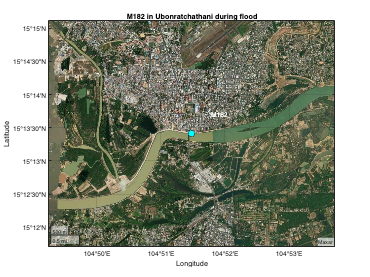

 
lat1 = 15.2235;
lon1 = 104.8580;
text1 = "M182";

figure
basemap = "satellite";
geobasemap(basemap)

geoplot(lat1, lon1, ...
    'LineStyle', 'none', 'Marker', 'o', 'MarkerSize', 10, ...
    'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'c');

gx = gca;

% Increase the zoom level here
desiredZoomLevel = 14;  % Adjust this value as needed
gx.ZoomLevel = desiredZoomLevel;        

txtDelta = 0.005;
text(lat1 + txtDelta, lon1 + txtDelta, text1, 'Color', 'w')

title("M182 in Ubonratchathani during flood");

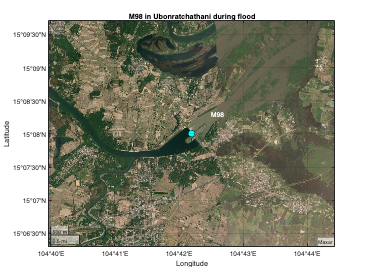

 
lat2 = 15.1334;
lon2 = 104.7033;
text2 = "M98";

figure
basemap = "satellite";
geobasemap(basemap)

% Plot the position of the second location
geoplot(lat2, lon2, ...
    'LineStyle', 'none', 'Marker', 'o', 'MarkerSize', 10, ...
    'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'c');

% Adjusting the current axes properties
gx = gca;
desiredZoomLevel = 14;  % Set your desired zoom level
gx.ZoomLevel = desiredZoomLevel;

% Offset for the text label
txtDelta = 0.005;

% Display the text label near the second location
text(lat2 + txtDelta, lon2 + txtDelta, text2, 'Color', 'w');

% Set the title of the plot
title("M98 in Ubonratchathani during flood");